# Lecture 17

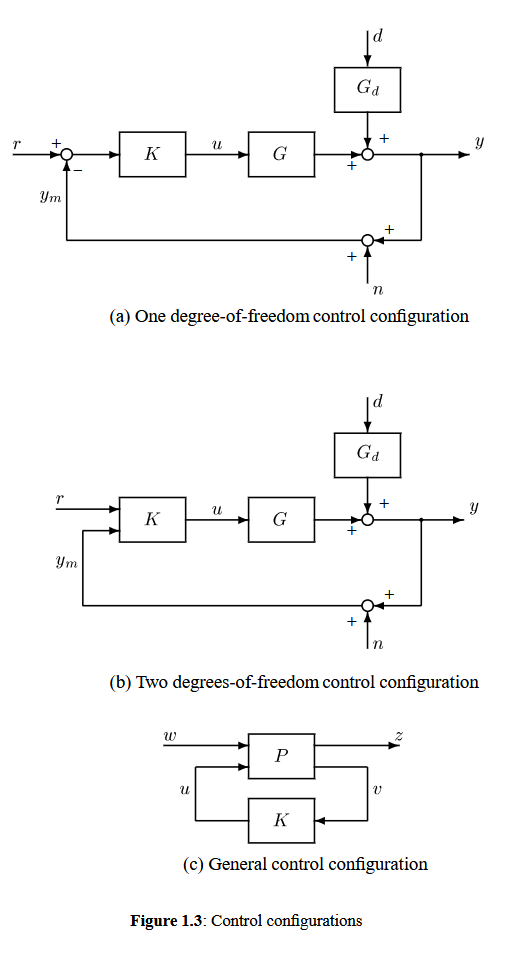

## Exercise 3.13

He means exercise 3.10

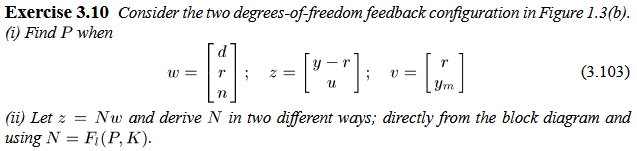

syms d r n y u y_m G_d G I K1 K2

P = [G_d -I 0 G
     0 0 0 I
     0 I 0 0
     G_d 0 I G];
P11 = P(1:2, 1:3)

$$P11 = \left(\begin{array}{ccc} G_{d} & -\text{I} & 0\\ 0 & 0 & 0 \end{array}\right)$$

P12 = P(1:2, 4)

$$P12 = \left(\begin{array}{c} G\\ \text{I} \end{array}\right)$$

P21 = P(3:4, 1:3)

$$P21 = \left(\begin{array}{ccc} 0 & \text{I} & 0\\ G_{d} & 0 & \text{I} \end{array}\right)$$

P22 = P(3:4, 4)

$$P22 = \left(\begin{array}{c} 0\\ G \end{array}\right)$$


K = [K1 K2]

$$K = \left(\begin{array}{cc} K_{1} & K_{2} \end{array}\right)$$

I = eye(2);
N = P11 + P12*K*inv(I - P22*K)*P21

$$N = \left(\begin{array}{ccc} G_{d}-\frac{G\,G_{d}\,K_{2}}{G\,K_{2}-1} & \text{I}\,\left(G\,K_{1}-\frac{G^{2}\,K_{1}\,K_{2}}{G\,K_{2}-1}\right)-\text{I} & -\frac{G\,\text{I}\,K_{2}}{G\,K_{2}-1}\\ -\frac{G_{d}\,\text{I}\,K_{2}}{G\,K_{2}-1} & \text{I}\,\left(\text{I}\,K_{1}-\frac{G\,\text{I}\,K_{1}\,K_{2}}{G\,K_{2}-1}\right) & -\frac{{\text{I}}^{2}\,K_{2}}{G\,K_{2}-1} \end{array}\right)$$

## Exercise 3.28

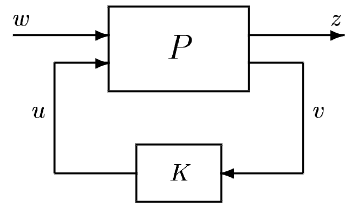

$\iff$ 


$$\Updownarrow$$


syms T G K
I = eye(1)

I = 1

eqn = T == G*K*inv(I + G*K)

$$eqn = T=\frac{G\,K}{G\,K+1}$$

K = solve(eqn, K)

$$K = \frac{T}{G-G\,T}$$

J is the plant (P), T is now the controller (K).

Working from N, where K is substituted with T.

P11 is zero as there's no + term. P12 is $G^{-1}$, since T is equivalent to K.

P21 and P22 is unity.

syms I
J = [0 inv(G)
     I I]

$$J = \left(\begin{array}{cc} 0 & \frac{1}{G}\\ \text{I} & \text{I} \end{array}\right)$$

## Exercise 3.29

syms A B C D I
H = [D C
     B A];

## Exercise 1 from note

s = tf('s')
k = 103.13; I_s = 14;
G = k/(I_s*s^2);

K_c = 0.0205; tau1 = 0.1;
tau2 = 5.5; tau3 = 0.3;
K = K_c * ((s + tau1)/s) * ((tau2*s + 1)/(tau3*s + 1));

M = 2; A = 0.01; omega_B = pi/5;
W_p = (s/M + omega_B) / (s + omega_B*A);